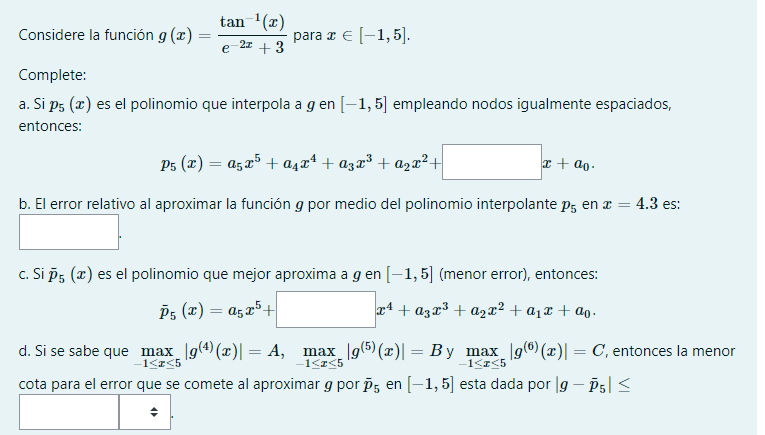

g = @(x) (atan(x))./(exp(-2*x)+3)

g = function_handle with value:
    @(x)(atan(x))./(exp(-2*x)+3)


a = -1

a = -1

b = 5

b = 5

n = 5

n = 5

g(4.3) % Real

ans = 0.4474

xe = linspace(a,b,n+1) % Nodos equidistanciados con n+1 cantidad de nodos

xe =    -1.0000    0.2000    1.4000    2.6000    3.8000    5.0000


ge = g(xe)

ge =    -0.0756    0.0538    0.3106    0.4005    0.4378    0.4578


[Cn, D] = newpoly (xe, ge) 

Cn =    -0.0016    0.0196   -0.0749    0.0587    0.2353    0.0049


D =    -0.0756         0         0         0         0         0
    0.0538    0.1078         0         0         0         0
    0.3106    0.2140    0.0442         0         0         0
    0.4005    0.0749   -0.0579   -0.0284         0         0
    0.4378    0.0311   -0.0183    0.0110    0.0082         0
    0.4578    0.0167   -0.0060    0.0034   -0.0016   -0.0016


(abs(g(4.3)-polyval(Cn,4.3)))/g(4.3)

ans = 0.0291

[C, X, Y] = cheby (g, n, a, b)

C =     0.2477    0.2949   -0.0922   -0.0132    0.0397   -0.0261


X =     4.8978    4.1213    2.7765    1.2235   -0.1213   -0.8978


Y =     0.4565    0.4442    0.4078    0.2869   -0.0282   -0.0811


% X son los nodos

[Cn, D] = newpoly (X, Y) 

Cn =    -0.0017    0.0211   -0.0826    0.0715    0.2366   -0.0007


D =     0.4565         0         0         0         0         0
    0.4442    0.0158         0         0         0         0
    0.4078    0.0270   -0.0053         0         0         0
    0.2869    0.0779   -0.0175    0.0033         0         0
   -0.0282    0.2343   -0.0540    0.0086   -0.0010         0
   -0.0811    0.0681    0.0784   -0.0360    0.0089   -0.0017


%COTA TEÓRICA
%%numero de derivada n +1, donde n es el grado del polinomio
syms x
f = @(x) (atan(x))./(exp(-2*x)+3)

f = function_handle with value:
    @(x)(atan(x))./(exp(-2*x)+3)


a = -1

a = -1

b = 5

b = 5

n = 5

n = 5

derivada=abs(diff(f(x),x,(n+1)))

der=matlabFunction(derivada)

der = function_handle with value:
    @(x)abs((exp(x.*-2.0).*1.0./(exp(x.*-2.0)+3.0).^2.*1.92e+2)./(x.^2+1.0)-exp(x.*-2.0).*1.0./(x.^2+1.0).^2.*1.0./(exp(x.*-2.0)+3.0).^2.*3.2e+2+exp(x.*-2.0).*1.0./(x.^2+1.0).^3.*1.0./(exp(x.*-2.0)+3.0).^2.*2.88e+2-(exp(x.*-4.0).*1.0./(exp(x.*-2.0)+3.0).^3.*5.76e+3)./(x.^2+1.0)+exp(x.*-4.0).*1.0./(x.^2+1.0).^2.*1.0./(exp(x.*-2.0)+3.0).^3.*1.92e+3+(exp(x.*-6.0).*1.0./(exp(x.*-2.0)+3.0).^4.*2.88e+4)./(x.^2+1.0)-exp(x.*-6.0).*1.0./(x.^2+1.0).^2.*1.0./(exp(x.*-2.0)+3.0).^4.*1.92e+3-(exp(x.*-8.0).*1.0./(exp(x.*-2.0)+3.0).^5.*4.608e+4)./(x.^2+1.0)+(exp(x.*-1.0e+1).*1.0./(exp(x.*-2.0)+3.0).^6.*2.304e+4)./(x.^2+1.0)-(x.*1.0./(x.^2+1.0).^4.*7.2e+2)./(exp(x.*-2.0)+3.0)-exp(x.*-2.0).*atan(x).*1.0./(exp(x.*-2.0)+3.0).^2.*6.4e+1+exp(x.*-4.0).*atan(x).*1.0./(exp(x.*-2.0)+3.0).^3.*3.968e+3-exp(x.*-6.0).*atan(x).*1.0./(exp(x.*-2.0)+3.0).^4.*3.456e+4+exp(x.*-8.0).*atan(x).*1.0./(exp(x.*-2.0)+3.0).^5.*9.984e+4-exp(x.*-1.0e+1).*atan(x).*1.0./(exp(x.*-2.0)+3.0).^6.*1.152e

X=linspace(a,b,10000)

X =    -1.0000   -0.9994   -0.9988   -0.9982   -0.9976   -0.9970   -0.9964   -0.9958   -0.9952   -0.9946   -0.9940   -0.9934   -0.9928   -0.9922   -0.9916   -0.9910   -0.9904   -0.9898   -0.9892   -0.9886   -0.9880   -0.9874   -0.9868   -0.9862   -0.9856   -0.9850   -0.9844   -0.9838   -0.9832   -0.9826   -0.9820   -0.9814   -0.9808   -0.9802   -0.9796   -0.9790   -0.9784   -0.9778   -0.9772   -0.9766   -0.9760   -0.9754   -0.9748   -0.9742   -0.9736   -0.9730   -0.9724   -0.9718   -0.9712   -0.9706


cota_1=max(der(X))

cota_1 = 53.4431

cota=(2.*((b-a).^(n+1)))./((4.^(n+1)).*factorial(n+1))

cota = 0.0316

cotatotal=cota_1.*cota

cotatotal = 1.6910


%Rta es cotatotal

%%CON ESTO SE CALCULA LA COTA TEORICA

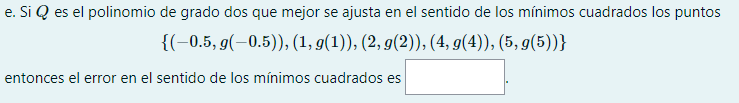

X = [-0.5 1 2 4 5]

X =   -0.500000000000000   1.000000000000000   2.000000000000000   4.000000000000000   5.000000000000000


Y = g(X)

Y =   -0.081081629571544   0.250498939490350   0.366810118706377   0.441889808717186   0.457793327720031


format short
C = lspoly (X, Y, 2)

C =    -0.0272
    0.2155
    0.0431


[A, B] = lsline0 (X, Y)

A = 0.0898

B = 0.0806

modelo = @(x) 0.0898*x+0.0806

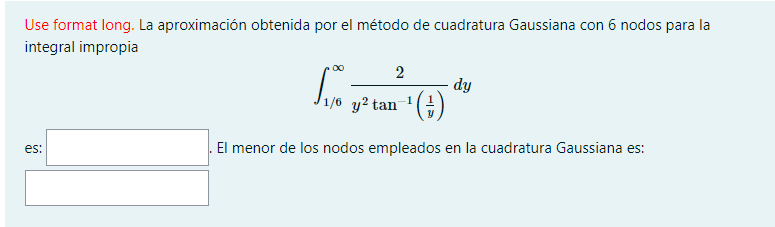

% INTEGRAL IMPROPIA
format long
syms x
f = 2/(x^2*atan(1/x))

$$f = \frac{2}{x^{2}\,\mathrm{atan}\left(\frac{1}{x}\right)}$$

f = matlabFunction(f,"vars",{x});
a=1/6;
b=inf;
N = 6 % Cantidad de nodos;

N =      6


[quad, raices, nodos, coefs] = impropias(f, a, b, N) %Esta funcion calcula integrales

quad =   14.752216205496993


raices =   -0.932469514203152
  -0.661209386466264
  -0.238619186083197
   0.238619186083197
   0.661209386466265
   0.932469514203152


nodos =    0.202591457390544
   1.016371840601207
   2.284142441750409
   3.715857558249590
   4.983628159398794
   5.797408542609457


coefs =    0.171324492379170
   0.360761573048139
   0.467913934572691
   0.467913934572691
   0.360761573048139
   0.171324492379170


%Impropias

[quad, raices, nodos, coefs] = GaussLegendre( f, a, b, N)

quad =    NaN


raices =   -0.932469514203152
  -0.661209386466264
  -0.238619186083197
   0.238619186083197
   0.661209386466265
   0.932469514203152


nodos =    Inf
   Inf
   Inf
   Inf
   Inf
   Inf


coefs =    0.171324492379170
   0.360761573048139
   0.467913934572691
   0.467913934572691
   0.360761573048139
   0.171324492379170
